%Variables to use
%X %Nodes in topology
%Y %k number of Shortest Paths
%Z %z Time required to compute the number of Shortest Paths

topology='VL2';
maxtopology=8;
max_k_shortest_paths=25;
tries_for_toc=50;

rows=(maxtopology-2)/2;
X(rows,max_k_shortest_paths)=0;
Y(rows,max_k_shortest_paths)=0;
Z(rows,max_k_shortest_paths)=0;
x(tries_for_toc)=1;

%Compute values
count=0;
for k=4:2:maxtopology
    count=count+1;
    source=k*1.5+1;
    G=graphTopology(false,false,topology,k);
    [last h]=size(G.Nodes.Name);
    for N=1:max_k_shortest_paths
        for z=1:tries_for_toc
        tic;
        kshortestpathsx(G,[last-1 last],N,'unweight');
        u=toc;
        u=u*1000;
        x(z)=u;
        end
        X(count,N)=last;
        Y(count,N)=N;
        Z(count,N)=mean(x);
    end
    k
end

k = 4

k = 6

k = 8

%Plot
tit='VL2-kShortestPaths'

tit = 'VL2-kShortestPaths'

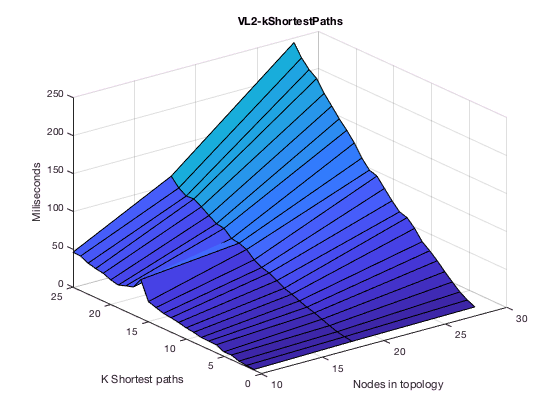


file=['Efficiency/VL2/',tit,'.mat'];
save(file, 'X', 'Y', 'Z');
fig=figure('Name',tit,'NumberTitle','off');
clf(fig);
surf(X,Y,Z);
xlabel('Nodes in topology');
ylabel('K Shortest paths');
zlabel('Miliseconds');
title(tit);
file=['Efficiency/VL2/',tit,'.fig'];
savefig(fig,file);
file=['Efficiency/VL2/',tit];
print(fig,file,'-dpng');